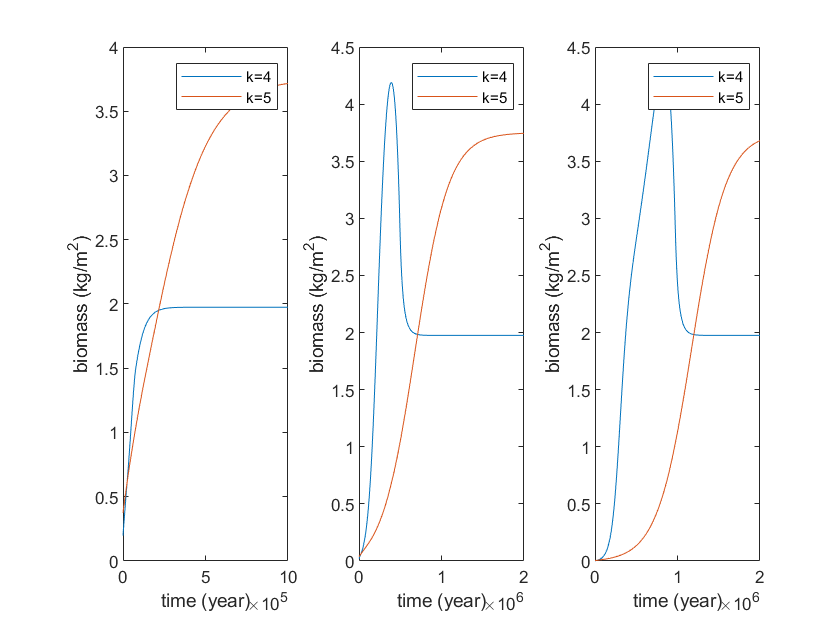

clc
clear
load b1.mat
load b2.mat
load a.mat
load vmax.mat
load maxx.mat
load M.mat
load dmdt.mat
load shadow.mat
load biomass.mat


%计算不同降水条件下的vk用(有震荡)
fun2=@(k,x,myvmax) a(5,k).*myvmax./(1+a(1,k).*exp(a(2,k).*(x-a(3,k))))+a(5,k).*myvmax./(1+a(1,k).*exp(-a(2,k).*(x-a(3,k)-a(4,k)))) - 1.5.*myvmax;
  

time = 10;%总时间
dt = 0.00001;%时间步长(越小越精确，但更占内存和时间)
len = round(time/dt);%计算总步数
m = M./100;          %初始生物量为最大生物量的0.01
minm = 0.01*min(min(M));%最小的生物量（防止灭绝）




k=[4 5];%在这里写要加入的植物代号（加k2就写2，加k3就写3）
[w,num]=size(k);%计算植物数量num
  


zx=800;%降水量波动中心值
bd=50;%降水量波动值（正100负100   共200）          %波动性调小
tq=rand(1,len);
tq=bd*(tq-0.5);
tq=tq+zx;%降水量tq



yin=m./biomass.*shadow;

%caoben=m(4:6);

mm=zeros(6,len);%记录各植物的数量
dmm=mm;
for t=dt:dt:time%随k2的生物量增长，k1的增长速率会如何变化
    tt=round(t/dt);
    other=0;
    for u=1:num%遍历全部植物

        f=k(u);
        
        
        

        %xz=minm-M(f);%允许共生和竞争
        xz=0;%只允许共生

        myvmax=vmax(f);
        for v=1:num
            other=other+b1(f,k(v))*m(k(v))^2+b2(f,k(v))*m(k(v));%计算其他植物对第u种的影响
        end
        
        ttrr=false;
        if (f==4 || f==5 || f==6)%草本在有木本的情况下增长速率翻倍
            %v=2;
            %for n =1:3
            v=max(0,yin(f)-sum(yin(1:3)))/yin(f)+1.5*sum(yin(1:3))/yin(f);
            ttrr=true;
        end
        
        
        dm=fun2(f,tq(tt),myvmax)*m(f)*(1- ( m(f)/( M(f)+max(xz,other))));
        
        if ttrr
            dm=dm*v;%有草本，加上增益
        end

        m(f)=m(f)+dm*dt;

        if m(f)<=0
            m(f)=minm;%种群数量不能为负
        end

        mm(f,tt)=m(f);
        dmm(f,tt)=dm;%fun2(f,tq(tt),myvmax);
    end
    yin=m./biomass.*shadow;
end

tt=1:len;

subplot(1, 3, 2)
plot(tt,mm(4,tt),tt,mm(5,tt))%画图

legend('k=4', 'k=5')%
legend('show')

xlabel('time (year)')
ylabel('biomass (kg/m^2)')
xlim([0 max(tt)])




%plot(tt,dmm(1,:),tt,dmm(2,:))%画图
%plot(tt,mm(1,:),tt,mm(4,:))%画图
%plot(tt,mm(6,:))%画图
%plot(tt,dmm(6,:))%画图

% jiange=16000;%间隔几个点
% for i=1:len/jiange
%     mmm(:,i)=mm(:,i*jiange);
% end
% surf(mmm')
% bar3(mmm);
%yy=1:6;
%plot3(tt,yy,mmm)